# Método de Coeficientes Indeterminados

# (El Modelo de Ciclos Económicos Reales)

Mauricio Tejada

ILADES - Universidad Alberto Hurtado

Noviembre 2018

## El Problema de Optimización

Hasen (1985): El problema de optimización del planificador central es el siguiente:


$$\begin{array}{rcl}
\max U_{0} & = & \sum_{t=0}^{\infty}\beta^{t}\left(\ln C_{t}-AN_{t}\right)\\
s.a &  & C_{t}+I_{t}=Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}\\
 &  & K_{t+1}=I_{t}+(1-\delta)K_{t}\\
 &  & \ln Z_{t+1}=\rho\ln Z_{t}+\epsilon_{t+1}\,\,\,\epsilon_{t+1}\sim N(0,\sigma)\\
 &  & K_{0},Z_{0}\,dado.
\end{array}$$


Alternativamente:


$$\begin{array}{rcl}
\max U_{0} & = & \sum_{t=0}^{\infty}\beta^{t}\left(\ln C_{t}-AN_{t}\right)\\
s.a &  & C_{t}+K_{t+1}=Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}+(1-\delta)K_{t}\\
 &  & \ln Z_{t+1}=\rho\ln Z_{t}+\epsilon_{t+1}\,\,\,\epsilon_{t+1}\sim N(0,\sigma)\\
 &  & K_{0},Z_{0}\,dado.
\end{array}$$


## Condiciones de Optimalidad

El lagranjeano intertemporal en valor presente:


$$L=\sum_{t=0}^{\infty}\beta^{t}\left[\ln C_{t}-AN_{t}+\lambda_{t}\left(Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}+(1-\delta)K_{t}-C_{t}-K_{t+1}\right)\right]$$


Condiciones de primer orden:


$$\begin{array}{rcl}
\frac{\partial L}{\partial C_{t}} & : & \beta^{t}\left[\frac{1}{C_{t}}-\lambda_{t}\right]=0\\
\frac{\partial L}{\partial N_{t}} & : & \beta^{t}\left[-A+\lambda_{t}(1-\alpha)Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}\right]\\
\frac{\partial L}{\partial K_{t+1}} & : & -\beta^{t}\lambda_{t}+\beta^{t+1}E_{t}\left[\lambda_{t+1}\left(\alpha Z_{t+1}K_{t+1}^{\alpha-1}N_{t+1}^{1-\alpha}+1-\delta\right)\right]\\
\frac{\partial L}{\partial\lambda_{t}} & : & Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}+(1-\delta)K_{t}-C_{t}-K_{t+1}=0
\end{array}$$


Tenemos el siguiente sistema de ecuaciones en diferencias (no lineal):


$$\begin{array}{rcl}
\frac{1}{C_{t}} & = & \beta E_{t}\left[\frac{1}{C_{t+1}}\left(\alpha Z_{t+1}K_{t+1}^{\alpha-1}N_{t+1}^{1-\alpha}+1-\delta\right)\right]\\
A & = & \frac{(1-\alpha)Z_{t}K_{t}^{\alpha}N_{t}^{-\alpha}}{C_{t}}\\
C_{t}+K_{t+1} & = & Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}+(1-\delta)K_{t}\\
\ln Z_{t+1} & = & \rho\ln Z_{t}+\epsilon_{t+1}
\end{array}$$


## Estado Estacionario

Entonces el estado estacionario resuelve (usamos $Z^* =1$):


$$\begin{array}{rcl}
1 & = & \beta\left[\alpha K^{*\alpha-1}N^{*1-\alpha}+1-\delta\right]\\
A & = & \frac{(1-\alpha)K^{*\alpha}N^{*-\alpha}}{C^{*}}\\
C^{*} & = & K^{*\alpha}N^{*1-\alpha}-\delta K^{*}
\end{array}$$


Para el cálculo del estado estacionario definimos primero los parámetros del modelo: 

alpha     = 0.36;   % Participacion del capital
delta     = 0.025;  % Tasa de depreciacion
beta      = 1/1.01; % Tasa de descuento (compatible con 1% de tasa de retorno)
rho       = 0.95;   % Coeficiente de autocorrelaci?n del shock tecnologico
sigma     = 0.712;  % Desviacion estandar del shock tecnologico  (Unidades: %)
A         = 2.5846; % Parametro de la funci?n de utilidad
zee       = 1;      % Normalizacion

Para calcular el estado estacionario del modelo, generamos el sistema de ecuaciones 

f = @(x) [beta*(alpha*zee*(x(1)^(alpha-1))*(x(2)^(1-alpha))+(1-delta)) - 1;
    A - ((1-alpha)*zee*(x(1)^alpha)*(x(2)^(-alpha))/x(3));
    zee*(x(1)^alpha)*(x(2)^(1-alpha)) - delta*x(1) - x(3)];

Usamos la función **fsolve** de Matlab:      

[xout,funv]=fsolve(f,[0.5;0.5;0.5]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



kee   = xout(1);
nee   = xout(2);
cee   = xout(3);
yee   = zee*(kee^alpha)*(nee^(1-alpha));
lamee = 1/cee;
ree   = alpha*zee*(kee^(alpha-1))*(nee^(1-alpha))+(1-delta);

disp(xout);

   12.7203
    0.3333
    0.9187



## Loglinealización

Re-escribimos el modelo para hacer más simple la log-linealización:


$$\begin{array}{rcl}
\frac{1}{C_{t}} & = & \beta E_{t}\left[\frac{R_{t+1}}{C_{t+1}}\right]\\
R_{t} & = & \alpha Z_{t}K_{t}^{\alpha-1}N_{t}^{1-\alpha}+1-\delta\\
A & = & \frac{(1-\alpha)Z_{t}K_{t}^{\alpha}N_{t}^{-\alpha}}{C_{t}}\\
C_{t}+K_{t+1} & = & Z_{t}K_{t}^{\alpha}N_{t}^{1-\alpha}+(1-\delta)K_{t}\\
\ln Z_{t+1} & = & \rho\ln Z_{t}+\epsilon_{t+1}
\end{array}$$


Entonces (definiendo ${x_{\;} }_t \;\;=\mathrm{ln}X_{t\;} -\mathrm{ln}X^* \;$)


$$\begin{array}{rcl}
c_{t} & = & E_{t}\left(c_{t+1}-r_{t+1}\right)\\
R^{*}r_{t} & = & \alpha K^{*\alpha-1}N^{*1-\alpha}\left(z_{t}+(\alpha-1)k_{t}+(1-\alpha)n_{t}\right)\\
0 & = & z_{t}+\alpha k_{t}-\alpha n_{t}-c_{t}\\
C^{*}c_{t}+K^{*}k_{t+1} & = & K^{*\alpha}N^{*1-\alpha}\left(z_{t}+\alpha k_{t}+(1-\alpha)n_{t}\right)+(1-\delta)K^{*}k_{t}\\
z_{t} & = & \rho z_{t-1}+\epsilon_{t}
\end{array}$$


Método de Coeficientes Indeterminados

Usamos ahora el método de coeficientes indeterminados de Uhlig (1997). Es un método de perturbación que resuelve el sistema de ecuaciones en diferencias estocástico linealizado. Para la aplicación del método, el sistema lineal es escrito como sigue:


$$\begin{array}{rcl}
Ax'+Bx+Cy+Dz & = & 0\\
E\left[Fx''+Gx'+Hx+Jy'+Ky+Lz'+Mz\right] & = & 0\\
z'=Nz+\epsilon' &  & E[\epsilon']=0
\end{array}$$


donde $x$ es el vector de variables de estado endógenas (de tamaño $m\times 1$), $y$ es el vector de variables de control (de tamaño $n\times 1$), y $z$ es el vector de variables de estado exógenas (de tamaño $k\times 1$). 

En el ejemplo:


$$x = k \\
y = [c, y, n, \lambda, r] \\
z = z $$


Declarando las matrices:

% para k(t+1):
AA = [ 0
    0
    0
    0
    kee ];

% para k(t):
BB = [ 0
    0
    alpha*yee/kee
    -alpha
    -(1-delta)*kee];

%Orden:   c       y                 n         lam   r
CC = [    1,      0,                0,         1,   0
    0,      1,               -1,         1,   0
    0,      -alpha*yee/kee,   0,         0,   ree
    0,      1,               -(1-alpha), 0,   0
    cee,    -yee,              0,         0,  0 ];

DD = [ 0
    0
    0
    -1
    0 ];

FF = [ 0 ];

GG = [ 0 ];

HH = [ 0 ];

JJ = [ 0,  0,  0,  1,  1];

KK = [ 0,   0,  0,  -1,  0];

LL = [ 0 ];

MM = [ 0 ];

NN = [rho];

Sigma = [ sigma^2  ];

Número de variables de estado (endógenas y exógenas) y de control.

[l_equ,m_states] = size(AA);
[l_equ,n_endog ] = size(CC);
[l_equ,k_exog  ] = size(DD);

La solución del problema son las funciones de política lineales dadas por:


$$\begin{array}{rcl}
x' & = & Px+Qz\\
y & = & Rx+Sz
\end{array}$$


donde los coeficientes por determinar son los elementos de las matrices $P,Q,R,S$.

**Cálculo de la matroz **$P$

La matriz $P$ resuleve la siguiente ecuación:


$$(F-JC^{-1}A)P^{2}-(JC^{-1}B+KC^{-1}A-G)P-(KC^{-1}B-H)  =  0$$


o altenativamente:


$$\Psi P^{2}-\Gamma P-\Theta  =  0$$


Psi  = FF - JJ/CC*AA;
Gamma = JJ/CC*BB + KK/CC*AA - GG;
Theta = KK/CC*BB - HH;

Xi = [Gamma Theta; eye(m_states) zeros(m_states,m_states)];
Delta = [Psi zeros(m_states,m_states); zeros(m_states,m_states) eye(m_states)];

% Aplicamos la descomposición QZ
[avec, aval] = eig(Delta,Xi,'qz');

% ordenamos de menos a mayor los autovalores
[d,ind] = sort(diag(aval));

avals = aval(ind,ind);
avecs = avec(:,ind);

PP_all = avecs*avals\avecs;

% Usamos las sólo las raices menores que 1
Ind = diag(PP_all) < 1;
PP = PP_all(Ind,Ind);

disp(PP);

    0.9420



Una vez hallada $P$, la matriz $R$ es hallada usando:


$$R=-C^{-1}(AP+B)$$


RR = -CC\(AA*PP + BB);

disp(RR);

    0.5315
    0.0551
   -0.4764
   -0.5315
   -0.0327



Quedan por resolver las matrices $S$ y $Q$. Definimos la matriz $V$ como:


$$V=\left[\begin{array}{cc}
I_{k}\otimes A & I_{k}\otimes C\\
N'\otimes F+I_{k}\otimes(FP+JR+G) & N'\otimes J+I_{k}\otimes K
\end{array}\right]$$


y por tanto $S$ y $Q$ resuleven:


$$V\times\left[\begin{array}{c}
vec(Q)\\
vec(S)
\end{array}\right]=\left[\begin{array}{c}
vec(D)\\
vec(LN+M)
\end{array}\right]$$


VV_11 = kron(eye(k_exog),AA);
VV_12 = kron(eye(k_exog),CC);
VV_21 = kron(NN',FF)+kron(eye(k_exog),(FF*PP+JJ*RR+GG));
VV_22 = kron(NN',JJ)+kron(eye(k_exog),KK);

VV = [ VV_11, VV_12
       VV_21, VV_22];

LLNN_plus_MM = LL*NN + MM;
QQSS_vec = - VV \ [ DD(:)
                    LLNN_plus_MM(:) ];  

QQ = reshape(QQSS_vec(1:m_states*k_exog),m_states,k_exog);
SS = reshape(QQSS_vec((m_states*k_exog+1):((m_states+n_endog)*k_exog)),n_endog,k_exog);
   
disp(QQ);

    0.1550



disp(SS);

    0.4696
    1.9429
    1.4732
   -0.4696
    0.0673



## Analisis de Impulso Respuesta

num_periodos = 12*6;
t = 1:num_periodos;
% El shock inicial es de una desviación estándar.
shock_inicial = ones(k_exog); % esto es, desvío 1%, podría ser sigma;

% Situación inicial: Estado estacionario
xx = zeros(num_periodos,m_states);
yy = zeros(num_periodos,n_endog);
zz = zeros(num_periodos,k_exog);

zz(2,:) = shock_inicial;
yy(2,:) = RR*xx(1,:) + SS*zz(1,:);

for i = 3:num_periodos
    zz(i,:) = NN*zz(i-1,:);
    xx(i,:) = PP*xx(i-1,:) + QQ*zz(i-1,:);
    yy(i,:) = RR*xx(i,:) + SS*zz(i,:);
end

Ahora graficamos las funciones impulso respuesta:

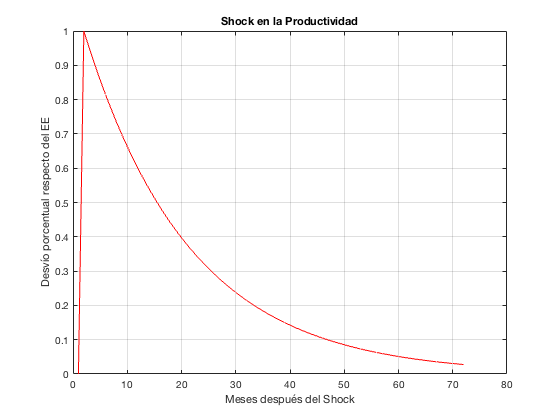

plot(t,zz,'-r')
title('Shock en la Productividad');
xlabel('Meses después del Shock');
ylabel('Desvío porcentual respecto del EE');
grid('on');

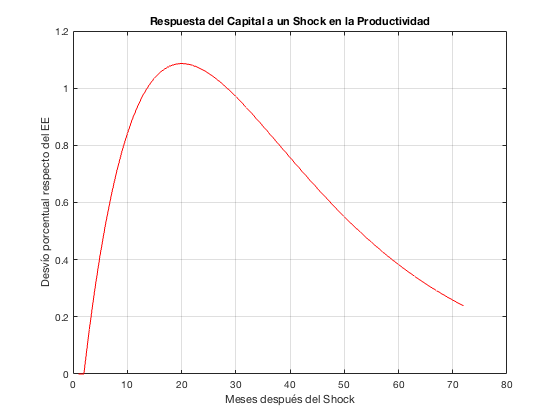

plot(t,xx,'-r')
title('Respuesta del Capital a un Shock en la Productividad');
xlabel('Meses después del Shock');
ylabel('Desvío porcentual respecto del EE');
grid('on');

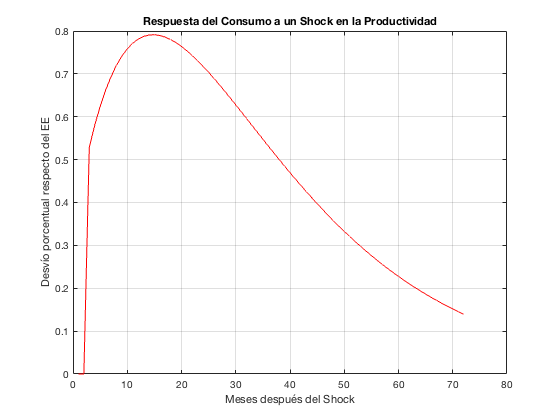

plot(t,yy(:,1),'-r')
title('Respuesta del Consumo a un Shock en la Productividad');
xlabel('Meses después del Shock');
ylabel('Desvío porcentual respecto del EE');
grid('on');

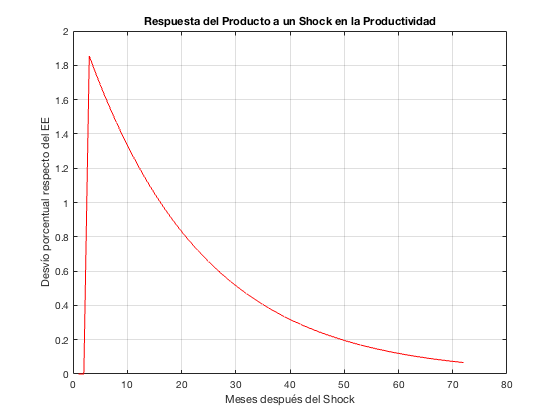

plot(t,yy(:,2),'-r')
title('Respuesta del Producto a un Shock en la Productividad');
xlabel('Meses después del Shock');
ylabel('Desvío porcentual respecto del EE');
grid('on');

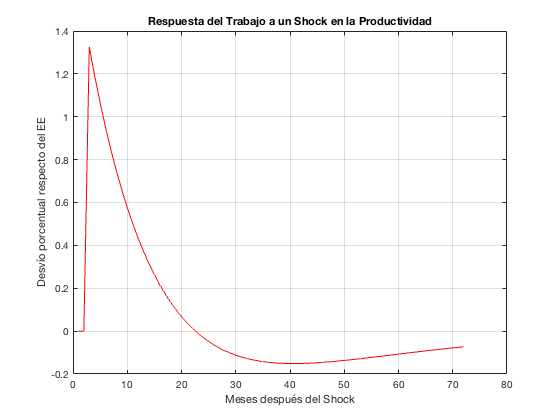


plot(t,yy(:,3),'-r')
title('Respuesta del Trabajo a un Shock en la Productividad');
xlabel('Meses después del Shock');
ylabel('Desvío porcentual respecto del EE');
grid('on');

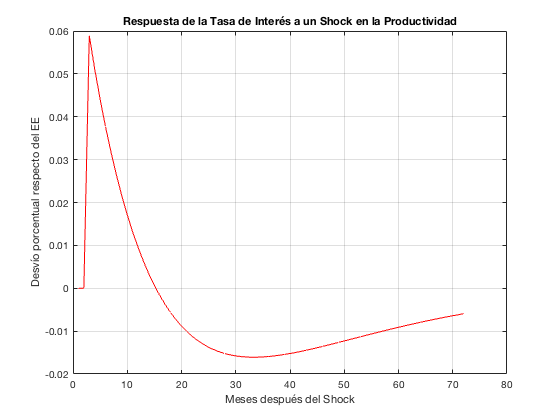

plot(t,yy(:,5),'-r')
title('Respuesta de la Tasa de Interés a un Shock en la Productividad');
xlabel('Meses después del Shock');
ylabel('Desvío porcentual respecto del EE');
grid('on');

## Simulaciones

% Semilla para simulación
rng(1706);
% Shock tecnológico
periodos_sim = 600;
t_sim = 1:periodos_sim; 
tdrop = 50;  % Eliminamos las primeras observaciones 
epsilon = sigma*randn(periodos_sim,1);

% Situación inicial: Estado estacionario
xx_sim = zeros(num_periodos,m_states);
yy_sim = zeros(num_periodos,n_endog);
zz_sim = zeros(num_periodos,k_exog);

zz_sim(2,:) = epsilon(1,:);
yy_sim(2,:) = RR*xx_sim(1,:) + SS*zz_sim(1,:);

for i = 3:periodos_sim
    zz_sim(i,:) = NN*zz_sim(i-1,:) + epsilon(i-1,:);
    xx_sim(i,:) = PP*xx_sim(i-1,:) + QQ*zz_sim(i-1,:);
    yy_sim(i,:) = RR*xx_sim(i,:) + SS*zz_sim(i,:);
end

Ahora graficamos las series simulades:

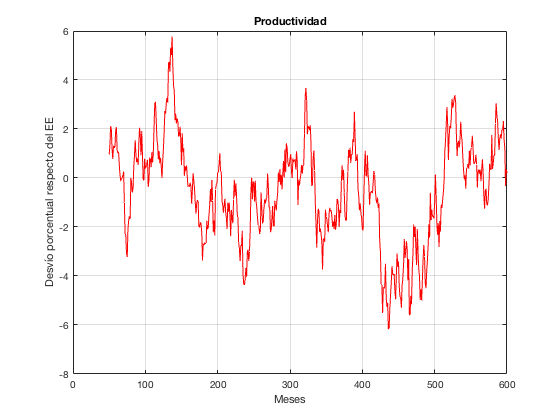

plot(t_sim(tdrop:end),zz_sim(tdrop:end),'-r')
title('Productividad');
xlabel('Meses');
ylabel('Desvío porcentual respecto del EE');
grid('on');

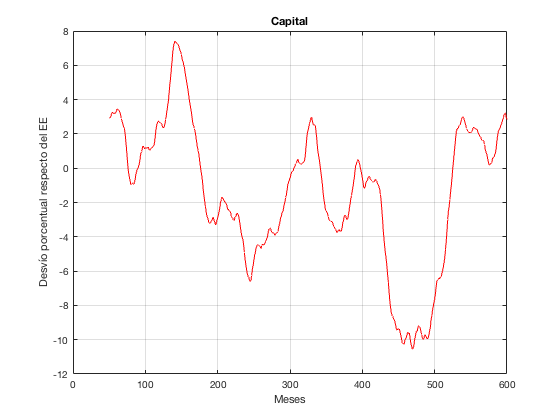

plot(t_sim(tdrop:end),xx_sim(tdrop:end),'-r')
title('Capital');
xlabel('Meses');
ylabel('Desvío porcentual respecto del EE');
grid('on');

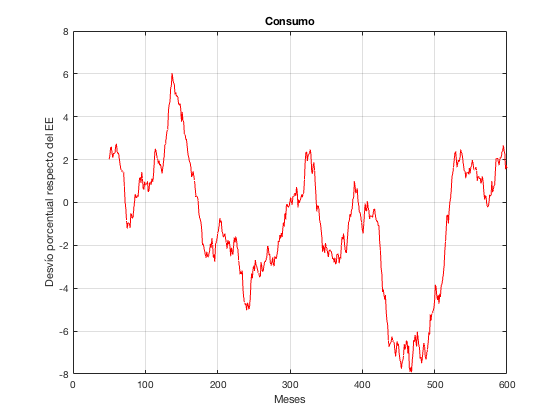

plot(t_sim(tdrop:end),yy_sim(tdrop:end,1),'-r')
title('Consumo');
xlabel('Meses');
ylabel('Desvío porcentual respecto del EE');
grid('on');

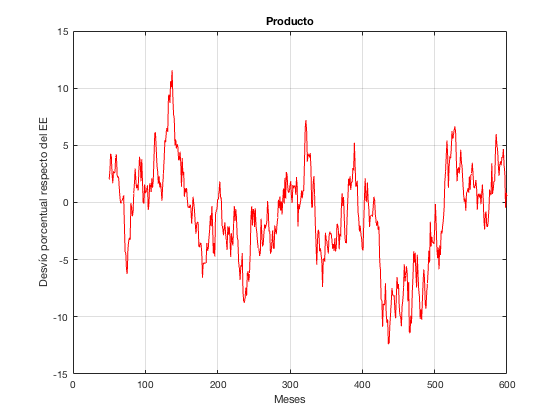

plot(t_sim(tdrop:end),yy_sim(tdrop:end,2),'-r')
title('Producto');
xlabel('Meses');
ylabel('Desvío porcentual respecto del EE');
grid('on');

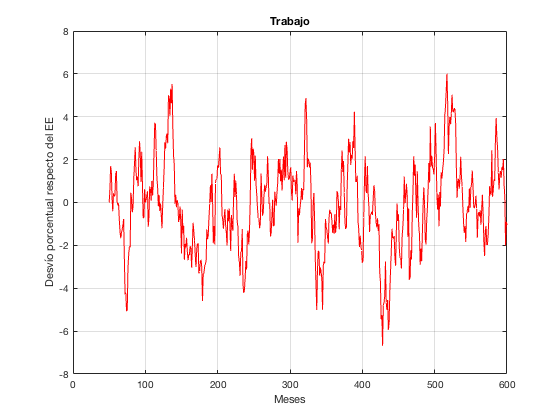

plot(t_sim(tdrop:end),yy_sim(tdrop:end,3),'-r')
title('Trabajo');
xlabel('Meses');
ylabel('Desvío porcentual respecto del EE');
grid('on');

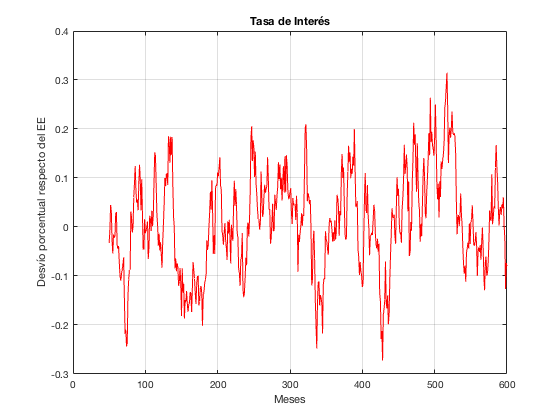

plot(t_sim(tdrop:end),yy_sim(tdrop:end,5),'-r')
title('Tasa de Interés');
xlabel('Meses');
ylabel('Desvío porcentual respecto del EE');
grid('on');